Set up the plots

% clear
% close all

Nmodes = 5;
f = 1:2:(Nmodes*2);
r = 1./((1:Nmodes)*pi);
t = linspace(0,1,200);

colors = lines(100);
lw = 1.25;
axisLims1 = [-1,1,-1,1]*sum(r)*1.01;
axisLims2 = [t(1),t(end),axisLims1(3:4)];

% variables
c = zeros(Nmodes,2);
theta = zeros(Nmodes);

% Set up the figure
figure('position',[0,0,1000,500])%,'visible','on')
ax1 = subplot('position',[0.05,0.1,0.4,0.7]);
tcirc = linspace(0,2*pi,500);
hold(ax1,"on")
for k = 1:Nmodes
    circHandles{k} = plot(ax1,0,0,'color',colors(k,:),'linewidth',lw);   
    lineHandles{k} = plot(ax1,0,0,'color',colors(k,:),'linewidth',lw);   
end
hold(ax1,"off")
axis equal
axis(axisLims1)
axis manual

ax2 = subplot('position',[0.55,0.1,0.4,0.7]);
signalHandle = plot(ax2,0,0,'color',colors(Nmodes,:),'linewidth',lw);
axis manual
box off
axis(ax2,axisLims2)


Plot between the axes

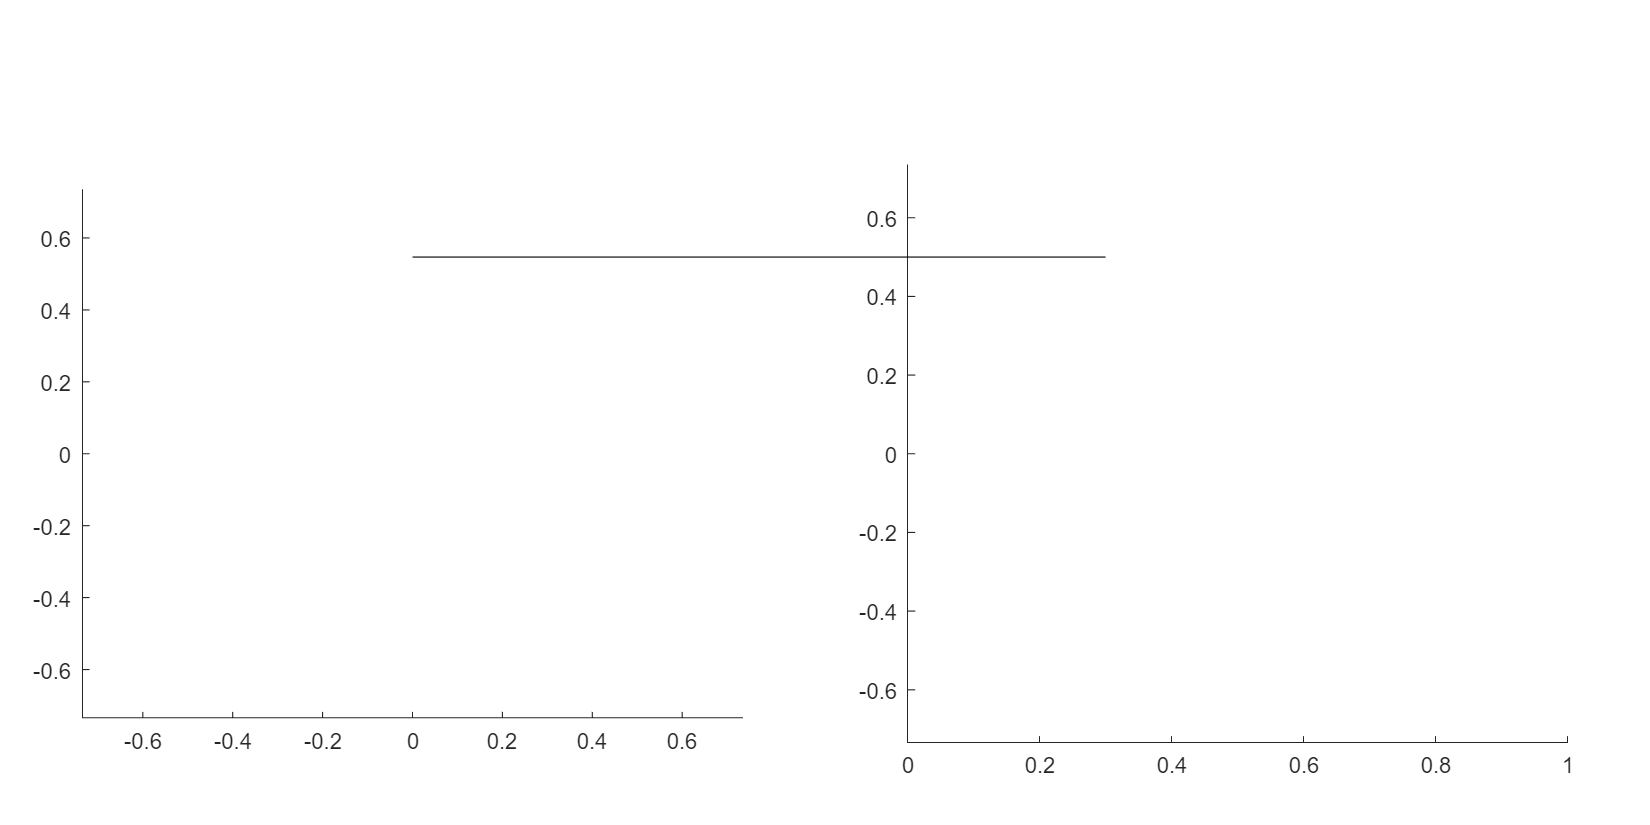

p1 = [0,0.5];
p2 = [0.3,0.5];

p1Fig = figPos(ax1,p1);
p2Fig = figPos(ax2,p2);
annotation('line',[p1Fig(1),p2Fig(1)],[p1Fig(2),p2Fig(2)])

function pFig = figPos(ax,p)

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    axUnits = ax.Units;
    ax.Units = 'normalized';
    xFig = x*(ax.Position(3))/(ax.XLim(2) - ax.XLim(1)) + ax.Position(1);
    yFig = y*(ax.Position(4))/(ax.YLim(2) - ax.YLim(1)) + ax.Position(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end